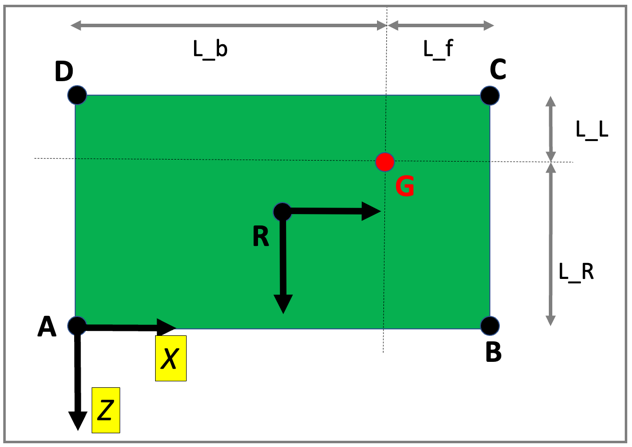

function G_rel_to_R = bh_calc_G_rel_to_R(L_b, L_f, L_L, L_R, options)
    arguments
        L_b (1,1) double
        L_f (1,1) double
        L_L (1,1) double
        L_R (1,1) double
        options.plot (1,1) logical = false;
    end
    R_rel_to_A = [ (L_b + L_f)/2;   0;    -1*(L_L + L_R)/2    ]; % = p_R - p_A
    G_rel_to_A = [  L_b         ;   0;    -1*L_R              ]; % = p_G - p_A
    
    G_rel_to_R = G_rel_to_A - R_rel_to_A;  % = (p_G - p_A) - (p_R - p_A) = p_G - p_R

    
    if(true == options.plot)
        LOC_plot(L_b, L_f, L_L, L_R, R_rel_to_A, G_rel_to_R);
    end
end

# Local Subfunctions only beyond this point

function LOC_plot(L_b, L_f, L_L, L_R, R_rel_to_A, G_rel_to_R)
    
    % NOTE:  the polyshape Y axis corresponds to OUR Z axis
    x = [0, (L_b+L_f), (L_b+L_f), 0];
    y = [0,        0, -1*(L_L + L_R), -1*(L_L + L_R)];
    
    pgon = polyshape(x,y);
    
    figure;
%    hax = axes("YDir","reverse")
        hax = axes();
        pgon.plot("Parent",hax);
        hold on
        grid on
        plot(x,y,'.k', 'MarkerSize',30);
        yline(-L_R, 'm', "LineWidth",3);
        xline(L_b, 'g', "LineWidth",3);
        
        plot((L_b+L_f)/2,-1*(L_L+L_R)/2, '.b', 'MarkerSize',30);
        
        G_rel_A = R_rel_to_A + G_rel_to_R;
        
        plot(G_rel_A(1), G_rel_A(3), '.r', 'MarkerSize',30);        
        axis equal
end